**Inital Preprocessing / Visualizing Raw Waveforms (70-380s)**

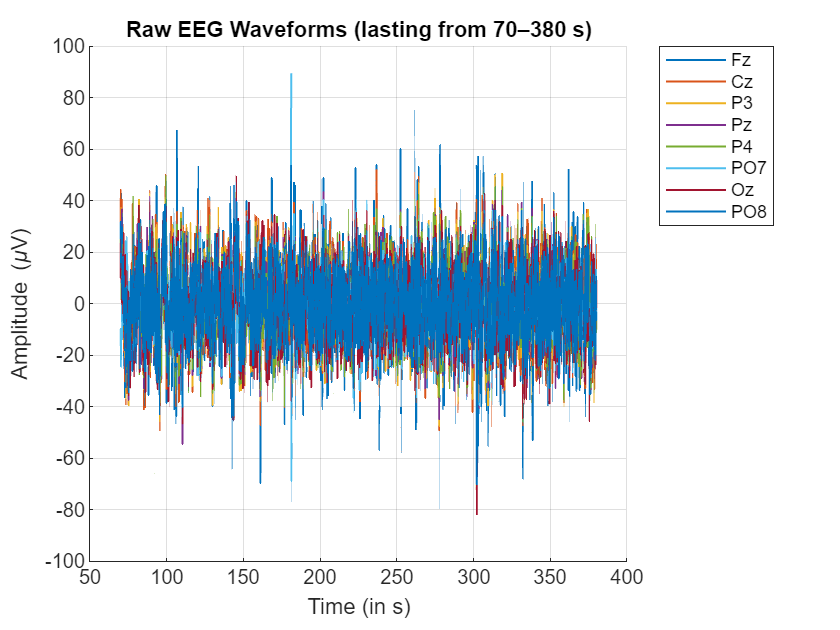

load('train2_group2_section1.mat');
% Layout of the channel electrodes:
%  1: the time starting at 0
%  2: Fz
%  3: Cz
%  4: P3
%  5: Pz
%  6: P4
%  7: PO7
%  8: Oz
%  9: PO8
% 10: Row/Column Flash (from about 1–12)
% 11: this would be the target indicator

chanNames = {'Fz','Cz','P3','Pz','P4','PO7','Oz','PO8'};
chanIdx = [2, 3, 4, 5, 6, 7, 8, 9];

%extract both time and eeg
t = y(1,:);          %in seconds
EEG = y(chanIdx,:); 

%Keeping only the information between 70–380 s (before and after this point
%feature substantial artifacts)
keep = (t >= 70 & t <= 380);
t = t(keep);
EEG = EEG(:, keep);

%removing dc drift 
for i = 1:size(EEG,1)
    EEG(i,:) = detrend(EEG(i,:), 'constant');
end

%same axis 
figure('Color','w');
hold on;
for i = 1:length(chanIdx)
    plot(t, EEG(i,:), 'LineWidth', 1);
end
hold off;

xlabel('Time (in s)');
ylabel('Amplitude (\muV)');
title('Raw EEG Waveforms (lasting from 70–380 s)');
legend(chanNames, 'Location', 'bestoutside');
grid on;

It was important that the first and the last portions of the recording were excluded since they contained large non-physiological artifacts that were likely caused by setup and shutdown transients. I believe that at the beginning of the session, electrode impedance was still stabilizing and that meant that the amplifier had not yet reached a steady baseline, which ended up producing abnormally high amplitude fluctuations. Following a similar theme, it appeared that the final seconds also showed these drift and motion artifacts as the subject relaxed and the recording was stopped. In order to ensure that only the stable and physiologically meaningful EEG activity went into the analysis, the data were trimmed to include only the period between the period between 70 s and 380 s, where the signal was clearly stable and free from this pervading noise.

**Use channels ten and eleven as triggers to cut the EEG data. (1 pt) **

**Cut 100ms before onset through 600ms after each flash and separate target and non-target  characters. (2 pts) **


%re using vars from prev. cell

flash  = y(10,:);    % the Row/Column flash (1–12 channel)
target = y(11,:);    %target indicator (where 1 = target flash, and 0 equal non-target)

%triggers restricted to that same 70–380s
flash  = flash(t >= 70 & t <= 380);
target = target(t >= 70 & t <= 380);

fs = 1 / mean(diff(t));   %sampling rate non hardcode

%epochs
win_pre  = 0.1;   %100ms before onset
win_post = 0.6;   %600ms after
nPre  = round(win_pre  * fs);
nPost = round(win_post * fs);

%finding the  flash onsets when it transitions from 0 → (anything in 1–12)
flash_shift = [0 flash(1:end-1)];
onsets = find((flash ~= 0) & (flash_shift == 0));

% store
epochs_target = {};
epochs_nontarget = {};

for i = 1:length(onsets)
    idx = onsets(i);
    if idx - nPre < 1 || idx + nPost > length(t)
        continue;  % skip the window if it ends up exceeding bounds
    end
    seg = EEG(:, idx - nPre : idx + nPost);
    
    if target(idx) == 1
        epochs_target{end+1} = seg;
    else
        epochs_nontarget{end+1} = seg;
    end
end

%Matrix channels by timepoints by trials
EEG_target    = cat(3, epochs_target{:});
EEG_nontarget = cat(3, epochs_nontarget{:});
t_epoch = (-nPre:nPost) / fs;   %time V

fprintf('Cut %d total flashes: %d target, %d non-target epochs.\n', ...
    numel(onsets), size(EEG_target,3), size(EEG_nontarget,3));

Cut 1096 total flashes: 183 target, 910 non-target epochs.


**Take the average response over trials and display the ERP waveforms for a) target and b) non target conditions for all channels and the average signal over all channels. (6 pts) **

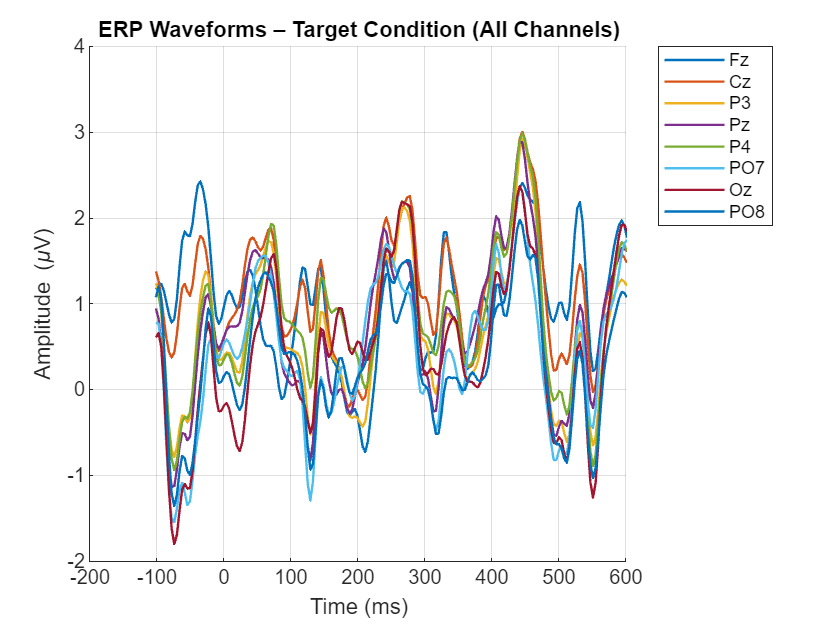

% prev vars

%computing the average ERP across all trials per channel i mean. 
ERP_target    = mean(EEG_target, 3);      %channels x tthe timepoints
ERP_nontarget = mean(EEG_nontarget, 3);

% grand averages across all the channels 
grand_target    = mean(ERP_target, 1);
grand_nontarget = mean(ERP_nontarget, 1);

%%ERP waveforms for all target conditions (across all channels)
figure('Color','w');
hold on;
for i = 1:size(ERP_target,1)
    plot(t_epoch*1000, ERP_target(i,:), 'LineWidth', 1.2);  %s --> ms
end
xlabel('Time (ms)');
ylabel('Amplitude (\muV)');
title('ERP Waveforms – Target Condition (All Channels)');
legend(chanNames, 'Location', 'bestoutside');
grid on;
hold off;

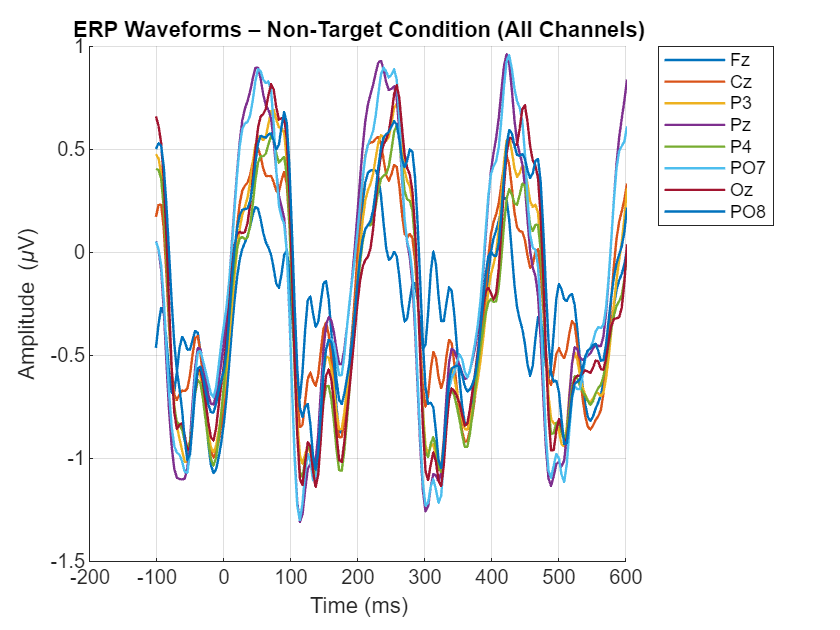


%%non-target condition
figure('Color','w');
hold on;
for i = 1:size(ERP_nontarget,1)
    plot(t_epoch*1000, ERP_nontarget(i,:), 'LineWidth', 1.2);
end
xlabel('Time (ms)');
ylabel('Amplitude (\muV)');
title('ERP Waveforms – Non-Target Condition (All Channels)');
legend(chanNames, 'Location', 'bestoutside');
grid on;
hold off;

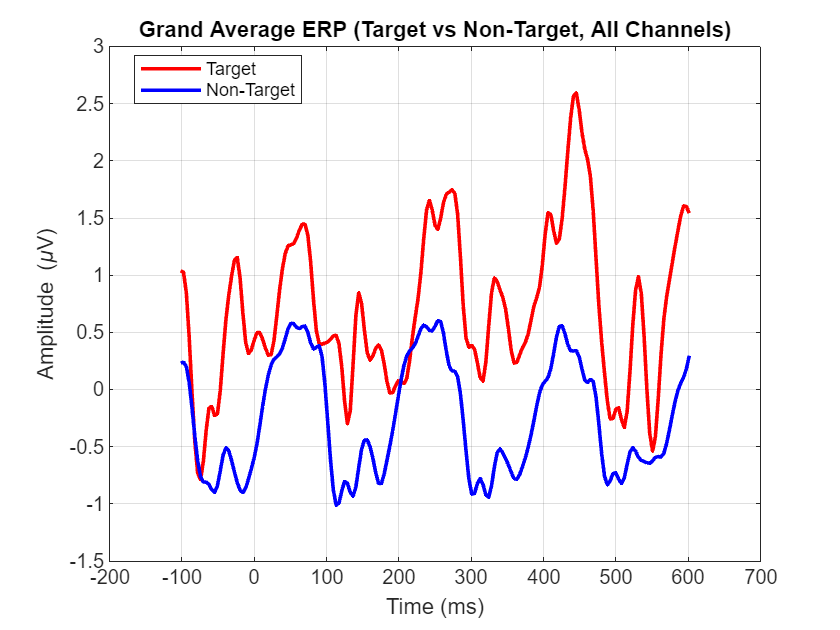


%%grand average ERP (taking the mean over all of the channels)
figure('Color','w');
plot(t_epoch*1000, grand_target, 'r', 'LineWidth', 1.8);
hold on;
plot(t_epoch*1000, grand_nontarget, 'b', 'LineWidth', 1.8);
xlabel('Time (ms)');
ylabel('Amplitude (\muV)');
title('Grand Average ERP (Target vs Non-Target, All Channels)');
legend({'Target','Non-Target'}, 'Location', 'best');
grid on;
hold off;

**Do you see a P300 response to the target? (1 pt) **

In my opinion, I observe that both the target and the non-target ERPs show similar timing in their deflections, perhaps indicating that they both share the same underlying sensory responses to the flashes. With that said, however, it appears that the target condition consistently maintains a higher, more positive amplitude (especially when between roughly 300–500 ms post-stimulus). I believe that this upward shift aligns with the expected timing and polarity that we would expect to come from the P300 component, which would reflect the brain’s recognition and then evaluation of any meaningful or attended stimuli. Although the response is not a single sharply isolated peak, I think that the mirrored shape with a sustained positive offset for targets provides enough clear evidence of a P300 effect.